# Using DIPFIT to fit one dipole to EEG or ERP scalp maps

This Live Script shows how to use EEGLAB command-line function to use the DIPFIT plugin to fit dipoles to raw ERP or EEG scalp maps. Note that it can't be done through a time-window, you need to specify a time point. Make sure to install **Fieldtrip** from the EEGLAB plugin manager.

### Load data

eeglab; close; % add path

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m


Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Fileio" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "HEDTools" v2.7.0 (see >> help eegplugin_hedtools)


EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "PICARD" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)


EEGLAB: adding "bids-matlab-tools" v5.2 (see >> help eegplugin_bids)
EEGLAB: adding "bids-validator" v1.1 (see >> help eegplugin_bidsvalidator)


EEGLAB: adding "bva-io" v1.7 (see >> help eegplugin_bva_io)


EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata)


EEGLAB: adding "corrmap" v2.1 (see >> help eegplugin_corrmap)


EEGLAB: adding "dipfit" v3.6 (see >> help eegplugin_dipfit)


EEGLAB: adding "erpsource" v1.0 (see >> help eegplugin_erpsource)
EEGLAB: adding "fieldtrip-" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "finderscourse" v1.1 (see >> help eegplugin_finderscourse)


EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


EEGLAB: adding "iirfilt" v1.03 (see >> help eegplugin_iirfilt)


EEGLAB: adding "lsl_app_matlabviewer" v1.0 (see >> help eegplugin_lsl_app_matlabviewer)


EEGLAB: adding "mffmatlabio" v3.5 (see >> help eegplugin_mffmatlabio)


EEGLAB: adding "mp_clustering" v2.0 (see >> help eegplugin_mp_clustering)


EEGLAB: adding "neuroscanio" v1.4 (see >> help eegplugin_neuroscanio)


EEGLAB: adding "nsgportal" v2.0 (see >> help eegplugin_nsgportal)


EEGLAB: adding "relica" v1.0 (see >> help eegplugin_RELICA)


EEGLAB: adding "roiconnect" v1.0 (see >> help eegplugin_roiconnect)


EEGLAB: adding "snapmaster" v1.0 (see >> help eegplugin_snapmaster)


EEGLAB: adding "xdfimport" v1.16 (see >> help eegplugin_xdfimport)


You are using the latest version of EEGLAB.


eeglabp = fileparts(which('eeglab.m'));
EEG = pop_loadset(fullfile(eeglabp, 'sample_data', 'eeglab_data_epochs_ica.set'));

pop_loadset(): loading file /data/matlab/eeglab/sample_data/eeglab_data_epochs_ica.set ...
Reading float file '/data/matlab/eeglab/sample_data/eeglab_data_epochs_ica.fdt'...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...


### Specify DIPFIT settings using MNI BEM model

dipfitdefs;
EEG = pop_dipfit_settings( EEG, 'hdmfile',template_models(2).hdmfile,'coordformat',template_models(2).coordformat,...
    'mrifile',template_models(2).mrifile,'chanfile',template_models(2).chanfile,...
   'coord_transform',[0.83215 -15.6287 2.4114 0.081214 0.00093739 -1.5732 1.1742 1.0601 1.1485] ,'chansel',[1:32] ); 

### Find the best-fitting dipole at 100-ms ERP

 Fitting may only be  performed at selected time points, not throughout a time window. 

latency = 0.100;
pt100 = round((latency-EEG.xmin)*EEG.srate);
erp = mean(EEG.data(:,:,:), 3);
[ dipole, model, TMPEEG] = dipfit_erpeeg(erp(:,pt100), EEG.chanlocs, 'settings', EEG.dipfit, 'threshold', 100);

eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
Scanning dipolar grid to find acceptable starting positions...
Transforming electrode coordinates to match head model
the input is component data with 2 components and 32 original channels
the input is raw data with 2 channels and 1 trials


reading 'headmodel' from file '/data/matlab/eeglab/plugins/dipfit/standard_BEM/standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 30 channels
selected 2 topographies


computing the leadfields for the gridsearch on the fly
creating sourcemodel based on user specified 3D grid
using electrodes specified in the configuration
2900 dipoles inside, 4012 dipoles outside brain
making tight grid
2900 dipoles inside, 2380 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 0 seconds and required the additional allocation of an estimated 1 MB
scanning grid
scanning grid location 2900/2900
found minimum after scanning for topography 1 on grid point [33.2609 -62.8261 7.72727]
found minimum after scanning for topography 2 on grid point [33.2609 -62.8261 7.72727]
the call to "ft_dipolefitting" took 8 seconds and required the additional allocation of an estimated 27 MB
Looking up brain area in the Desikan-Killiany Atlas
Component 1: area precuneus R
Component 2: area precuneus R
Done
Scanning terminated. Refining dipole locations...
Searching dipoles locations...
Transforming electrode coordinates to match head model
the input is component data with 2 co

reading 'headmodel' from file '/data/matlab/eeglab/plugins/dipfit/standard_BEM/standard_vol.mat'
using electrodes specified in the data
determining source compartment (3)
projecting electrodes on skin surface
combining electrode transfer and system matrix
selected 30 channels
selected 1 topographies


                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4        0.0956949                      0.000538
     1          20        0.0954064            820       0.000456  
     2          24        0.0945261              1       5.16e-05  
     3          28        0.0945104              1       1.65e-05  
     4          32        0.0945089              1       5.34e-06  
     5          36        0.0945088              1       1.33e-06  
     6          40        0.0945088              1        8.4e-08  
     7          44        0.0945088              1       8.27e-09  
     8          48        0.0945088              1       1.06e-09  
     9          64        0.0945088       0.476491       1.27e-09  

Local minimum possible.

fminunc stopped because it cannot decrease the objective function
along the curr

### Plot the dipole on 3-D map

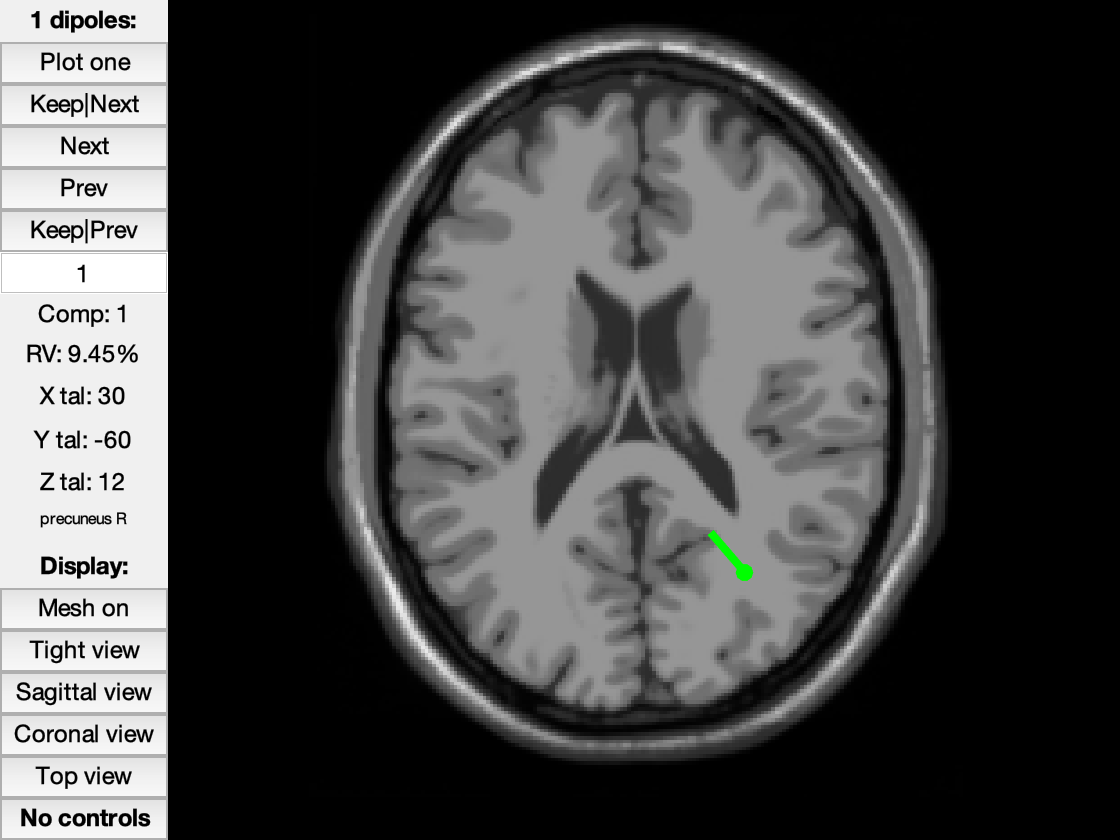

pop_dipplot(TMPEEG, 1, 'normlen', 'on');

### Plot the dipole and the scalp map

Plotting...


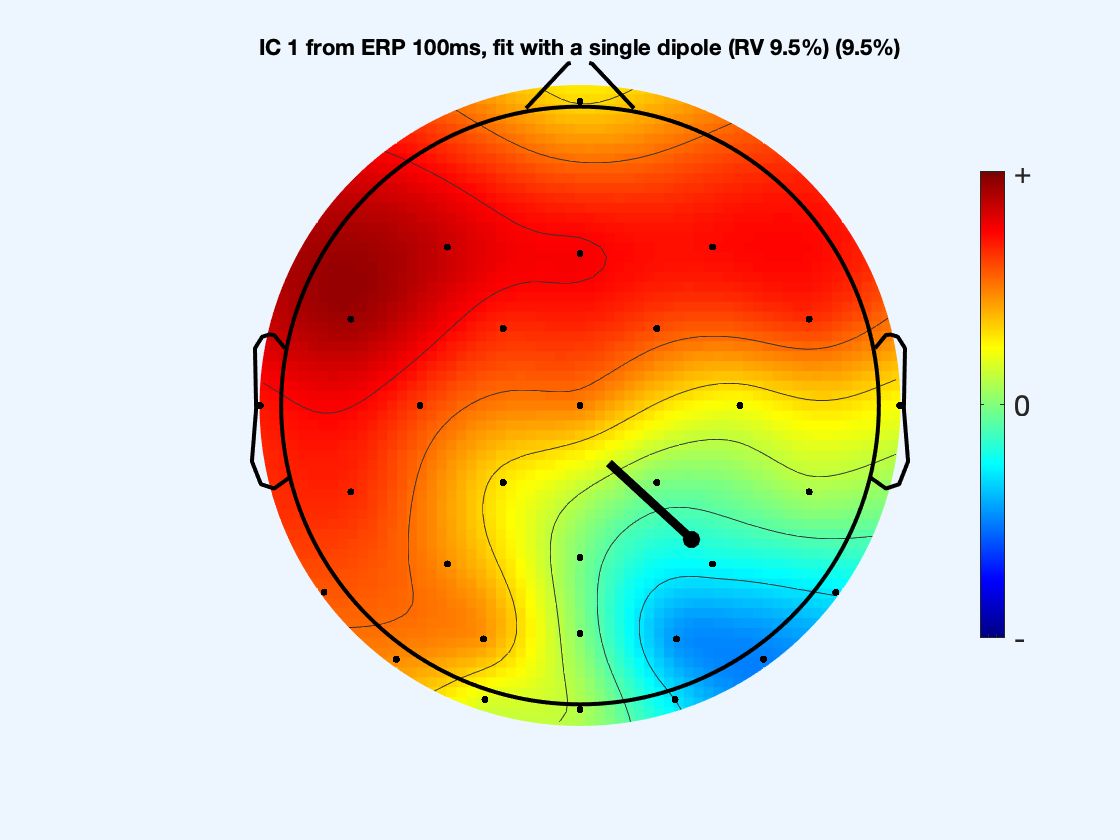

figure; pop_topoplot(TMPEEG,0,1, [ 'ERP 100ms, fit with a single dipole (RV ' num2str(dipole(1).rv*100,2) '%)'], 0, 1);